clc;
clear all;
close all;

## Question 1



%Question 1

%declaring constants
w = [1; -2; 0.5];
N = 200;

%uniformely distributed values of x in the range -5 to 5
x = (2*rand(N,1)-1)*5;
x_squared = x.^2;
X = [ones(N,1) x x_squared];

%generating a vector of gaussian distributed noise
n = normrnd(0,1,[N, 1]);

% generating t
t = X*w + n;

%disp(["size of x: ",num2str(size(x))," size of x_squared: ",num2str(size(x_squared)), " size of X: ", num2str(size(X)), " size of n: ", num2str(size(n)), "size of w: ", num2str(size(w))])

### Quadratic Model

%training the model
w_hat =((X'*X)^(-1))*X'*t; %Quadratic


%testing the model
plot_x = [-5.1:0.01:5.1]';
plot_X = [ones(length(plot_x),1) plot_x plot_x.^2];
t_hat = plot_X*w_hat;

disp(['trained weights of Quadratic Model are: ', num2str(w_hat')]);

trained weights of Quadratic Model are: 0.99582     -1.9642     0.49872


### Linear Model

%training the model
X_linear = X(:,1:2);
w_hat_linear = ((X_linear'*X_linear)^(-1))*X_linear'*t;

%testing the model
plot_X_linear = plot_X(:,1:2);
t_hat_linear = plot_X_linear*w_hat_linear;

disp(['trained weights of Linear Model are: ', num2str(w_hat_linear')]);

trained weights of Linear Model are: 5.204      -1.885


### Plots

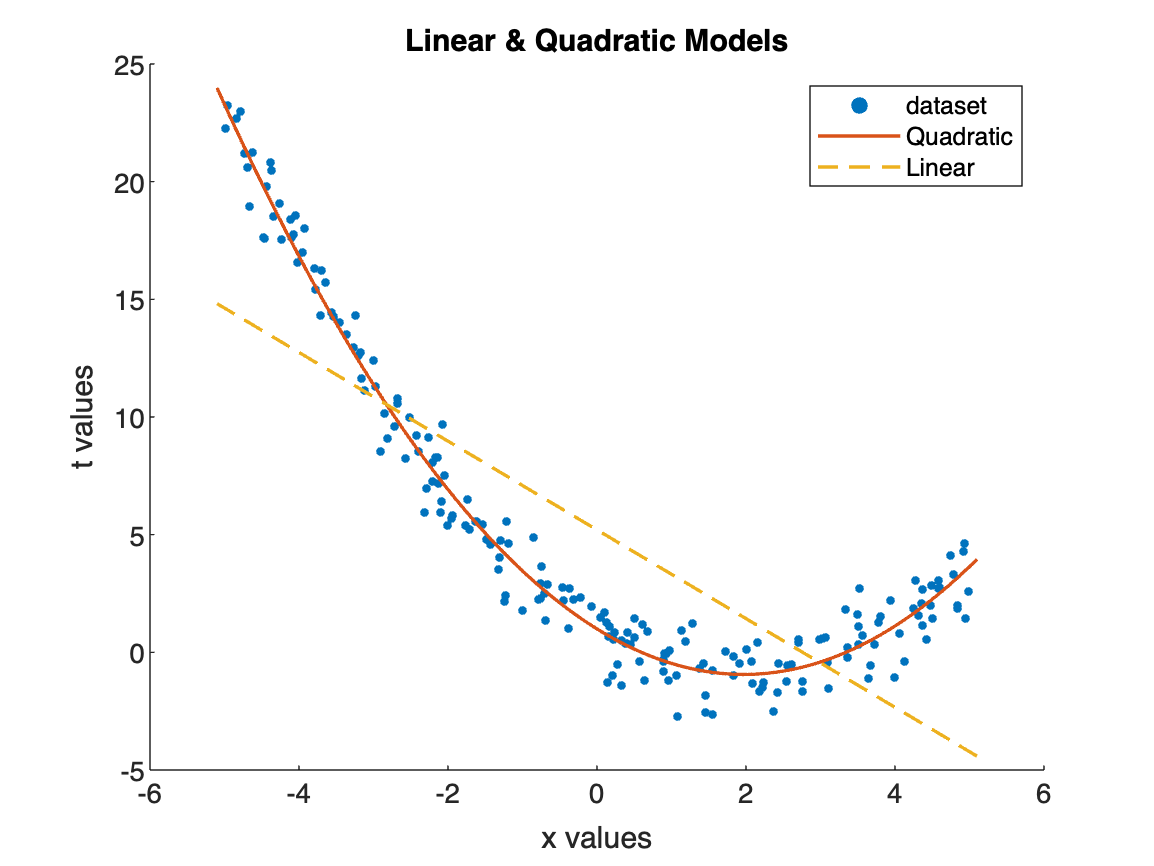

hold on;
figure(1);
scatter(x,t,10, 'filled')
plot(plot_x,t_hat,'LineWidth',1.25)
plot(plot_x, t_hat_linear, '--', 'LineWidth',1.25)
title('Linear & Quadratic Models')
ylabel('t values')
xlabel('x values')
legend('dataset', 'Quadratic', 'Linear')